## Theoretical ozone number density model:


$$N_{O_3 } \left(z\right)=\frac{1}{\Delta \sigma_{O_3 } \left(z\right)}\left\lbrack \frac{1}{2}\left\lbrace \frac{\partial }{\partial z}\left(\ln \frac{P_{\textrm{off}} \left(z\right)}{P_{\textrm{on}} \left(z\right)}\right)+\Lambda \beta \left(z\right)+\Lambda \eta \left(z\right)\right\rbrace -\Delta \sigma_M N_a \left(z\right)-\Delta \alpha_p \left(z\right)-\left(\sum_{\textrm{ig}} \Delta \sigma_{\textrm{ig}} \left(z\right)N_{\textrm{ig}} \left(z\right)\right)\right\rbrack$$



$$\Lambda \beta \left(z\right)=\frac{\delta }{\delta z}\left(\ln \frac{\beta_{\textrm{on}} \left(z\right)}{\beta_{\textrm{off}} \left(z\right)}\right)$$



$$\Lambda \eta \left(z\right)=\frac{\delta }{\delta z}\left(\ln \frac{\eta_{\textrm{on}} \left(z\right)}{\eta_{\textrm{off}} \left(z\right)}\right)$$


$\Delta \sigma_{O_3 } \left(z\right)$: ozone absorption cross section differential

$\Delta \sigma_M$:  Rayleigh cross section differential

$\Delta \sigma_{\textrm{ig}} \left(z\right)$: absorption cross section differential of constituent ig

$\Delta \alpha_p \left(z\right)$: extinction differential due to particles

$\beta \left(z\right)$: bacscatter coefficient including particulate and molecular backscatter

$\eta \left(z\right)$: optical efficiency including optical and spectral transmittance and geometric obstruction

## Practical DIAL model:

Ignore particulate extinction and backcatter, as well as overlap function differences for now


$$N_{O_3 } \left(z\right)=\frac{1}{\Delta \sigma_{O_3 } \left(z\right)}\left\lbrack \frac{1}{2}\frac{\partial }{\partial z}\left(\ln \frac{P_{\textrm{off}} \left(z\right)}{P_{\textrm{on}} \left(z\right)}\right)-\Delta \sigma_M N_a \left(z\right)-\left(\sum_{\textrm{ig}} \Delta \sigma_{\textrm{ig}} \left(z\right)N_{\textrm{ig}} \left(z\right)\right)\right\rbrack$$


Signal filtering: $S_m \left(k\right)=\sum_{p=-n}^n C_p \left(k\right)S_u \left(k\right)$


$$z\to z\left(k\right)\;\textrm{for}\;k=1,n_k$$



$$\frac{\partial }{\partial z}\left(\ln \frac{P_{\textrm{on}} \left(k\right)}{P_{\textrm{off}} \left(k\right)}\right)\to S\left(k\right)=\frac{1}{\delta z}\sum_{p=-n}^n C_p \left(k\right)*\ln \left(\frac{P_{\textrm{on}} \left(k+p\right)}{P_{\textrm{off}} \left(k+p\right)}\right)$$


Ozone number density as a function of range bin:


$$N_{O_3 } \left(k\right)=\frac{1}{\Delta \sigma_{O_3 } \left(k\right)}\left\lbrack \frac{1}{2}S\left(k\right)-\Delta \sigma_M N_a \left(k\right)-\left(\sum_{\textrm{ig}} \Delta \sigma_{\textrm{ig}} \left(k\right)N_{\textrm{ig}} \left(k\right)\right)\right\rbrack$$


Ozone mixing ratio as a function of range bin:


$$q_{O_3 } \left(k\right)=\frac{1}{\Delta \sigma_{O_3 } \left(k\right)}\left\lbrack \frac{1}{2}\frac{S\left(k\right)}{N_a \left(k\right)}-\Delta \sigma_M -\left(\sum_{\textrm{ig}} \Delta \sigma_{\textrm{ig}} \left(k\right)q_{\textrm{ig}} \left(k\right)\right)\right\rbrack$$


clc; clearvars;

addpath(genpath("./proc_functions"));

input_data_paths = ["./sample_data/";
                    "./../o3_lidar_data/";
                    "./../../../OneDrive - The City College of New York\Documents\lidar_data2\trailer_lidar_data\"];

output_data_paths = ["./sample_result/";
                     "./../o3_lidar_results/"];

data_path       = input_data_paths(1);
result_path     = output_data_paths(1);
data_format     = "bin";
date            = datetime("2025-09-19", "InputFormat", "uuuu-MM-dd");
date_str = string(datetime(date,"Format","uuuuMMdd"));
prefix = "ol";
fs = 16;

if ~exist(result_path,"dir")
    mkdir(result_path)
end

output_filename = "o3_lidar_" + date_str + ".mat";

n_channels = 8;
min_avg = 30;
bg_bins = 2666;
td = 270;
dz = 3.75;
min_toggle = 3;
max_toggle = 60;

% On and off wavelengths
lam_on = 287.2 * 1e-9; % m
lam_off = 299.1 * 1e-9; % m

fr_fl_M1 = 11; fr_fl_M2 = 351; fr_fl_h1 = 1.2; fr_fl_h2 = 10;
nr_fl_M1 = 11; nr_fl_M2 = 121; nr_fl_h1 = .2; nr_fl_h2 = 1.2;

o3_params_fr = params_struct(lam_on,lam_off,n_channels,min_avg,bg_bins,td,dz,min_toggle,max_toggle,fr_fl_M1,fr_fl_M2,fr_fl_h1,fr_fl_h2);
o3_params_nr = params_struct(lam_on,lam_off,n_channels,min_avg,bg_bins,td,dz,min_toggle,max_toggle,nr_fl_M1,nr_fl_M2,nr_fl_h1,nr_fl_h2);

Read raw data

return data, times and configurations

[bins, files, TR, an/pc]

[raw_data,times,configs] = read_lidar_datafiles(data_path+date_str,data_format,prefix);

% Use midpoint time to represent time
% TODO: make use of start and end times
times = times(:,2);

This section has to be redone better

Convert each dataset to physical units

num_bins = size(raw_data,1);
num_files = size(raw_data,2);
num_devices = size(raw_data,3);

scaled_data = NaN(size(raw_data));
h = NaN(num_bins,num_files,num_devices);

for i = 1:num_files
    temp_config = configs(i);
    for j = 1:num_devices
        % TODO: remove hardcoded 40 MHz
        scaled_data(:,i,j,1) = scale_binary_analog(raw_data(:,i,j,1),temp_config.range(j),temp_config.adcbits(j),temp_config.shots(j));
        scaled_data(:,i,j,2) = scale_binary_pc(raw_data(:,i,j,2),40,temp_config.shots(j));

        h(:,i,j) = (1:num_bins).*temp_config.binwidth(j);
    end
end

hkm = h./1000;
% TODO: potentially handle different bin width for different profiles,
% right now hkm is a single profile
hkm = hkm(:,1,1);

out_data_fr = struct;
out_data_fr.an_on = scaled_data(:,:,1,1);
out_data_fr.pc_on = scaled_data(:,:,1,2);
out_data_fr.hkm = hkm;

out_data_fr.an_off = scaled_data(:,:,2,1);
out_data_fr.pc_off = scaled_data(:,:,2,2);

out_data_nr = struct;
out_data_nr.an_on = scaled_data(:,:,3,1);
out_data_nr.pc_on = scaled_data(:,:,3,2);
out_data_nr.hkm = hkm;

out_data_nr.an_off = scaled_data(:,:,4,1);
out_data_nr.pc_off = scaled_data(:,:,4,2);

Perform DIAL retreival for FR and NR seperately

output_fr = O3_quicklook(out_data_fr,times,configs,o3_params_fr);
output_nr = O3_quicklook(out_data_nr,times,configs,o3_params_nr);
times_avg = output_fr.on.times_avg;

Merge NR and FR ozone

start_merge = .5;
end_merge = 1.2;
[No3_merged,w_fr_nr] = merge_profiles(output_nr.No3,output_fr.No3,hkm,start_merge,end_merge);
qo3_merged = merge_profiles(output_nr.qo3 - output_nr.Dqo3,output_fr.qo3 - output_fr.Dqo3,hkm,start_merge,end_merge);

Save result

result = struct;
result.configs = configs;
result.output_fr = output_fr;
result.output_nr = output_nr;
result.No3_merged = No3_merged;
result.qo3_merged = qo3_merged;
result.w_fr_nr = w_fr_nr;

save(fullfile(result_path,output_filename),"result")

Masking low quality data

% SNR Mask
min_snr = 50;
fr_on_snr_mask = output_fr.on.SNR > min_snr;
fr_off_snr_mask = output_fr.off.SNR > min_snr;

nr_on_snr_mask = output_nr.on.SNR > min_snr;
nr_off_snr_mask = output_nr.off.SNR > min_snr;

if false==true
    figure;
    i = imagesc(times_avg,hkm,output_fr.on.SNR);
    colorbar
    colormap('hot')
    set(gca,'YDir','Normal')
    set(gca,"ColorScale","log")
    ylim([0 10])
end

n_prof = length(times_avg);
id = 1;

if false == true
    plot_stages("on","an",[0 20],[0.0001 230.1],1,output_fr,"FR")
    plot_stages("on","pc",[0 23],[0.1 1000],1,output_fr,"FR")
    plot_stages("on","an",[0 3],[0.1 500],1,output_nr,"nR")
    plot_stages("on","pc",[0 8],[0.1 1000],1,output_nr,"nR")
end 
if false == true
    plot_anpc_merge("on",[0 7],[0.1 65230.1],id,output_fr,"FR")
    plot_anpc_merge("on",[0 3],[0.1 42330.1],id,output_nr,"NR")
end

if false== true
    ND_plot(times_avg,output_nr.hkm,output_nr.No3,[0 5*10^18],[0 10],"NR Ozone Number Density")
    ND_plot(times_avg,hkm,output_fr.No3,[0 5*10^18],[0 10],"FR Ozone Number Density")
    ND_plot(times_avg,hkm,No3_merged,[0 5*10^18],[0 10],"Ozone Number Density")
end

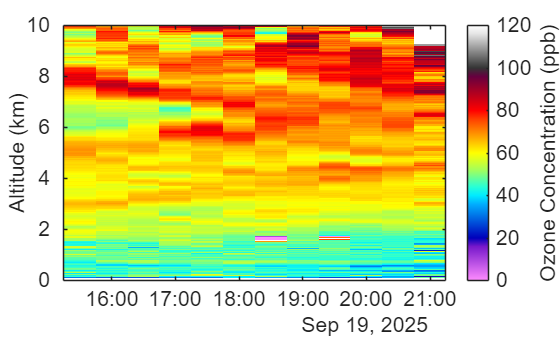

if true== true
    qo3_nr_plt = output_nr.qo3;
    qo3_fr_plt = output_fr.qo3;
    qo3_merged_plt = qo3_merged;
    if true == true
        qo3_nr_plt(~(nr_on_snr_mask & nr_off_snr_mask)) = NaN;
        qo3_fr_plt(~(fr_on_snr_mask & fr_off_snr_mask)) = NaN;

    end
    % ND_plot(times_avg,hkm,qo3_nr_plt,[0 120],[0 5],"NR Ozone Mixing Ratio")
    % ND_plot(times_avg,hkm,qo3_fr_plt,[0 120],[0 12],"FR Ozone Mixing Ratio")
    ND_plot(times_avg,hkm,qo3_merged_plt,[0 120],[0 10],"","Altitude (km)", "Ozone Concentration (ppb)", "",fs)
end

% save('lidar_data.mat',"times_avg","hkm","qo3_merged_plt");

if false==true
    figure;
    plot(hkm,result.output_fr.Dqo3(:,1))
    xlim([0 10])
end

Uncertainty

% u_Pon_DET_fr = uP_DET(P,R);

function plot_anpc_merge(wl,x_lim,y_lim,id,output,title_str)
    hkm = output.hkm;
    kn = length(hkm);

    ds = output.(wl);
    an_bg_rem = ds.an_bg_rem(:,id);
    pc_dt_bg_rem = ds.pc_dt_bg_rem(:,id);
    % ds_stats = ds.stats{id};

    figure;
    hold on
    plot(hkm,ds.pc_dt_bg_rem(1:kn,id),"DisplayName","PC")
    plot(hkm,ds.glued(1:kn,id),"DisplayName","AN-PC Merged")

    glued_idx = ds.glued_valid;
    glued_idx = glued_idx(:,id);
    hkm_glued = hkm(glued_idx);
    pc_dt_bg_rem_glued = ds.pc_dt_bg_rem(glued_idx,id);
    scatter(hkm_glued,pc_dt_bg_rem_glued)
    % scatter(hkm_glued(ds_stats.w==0),pc_dt_bg_rem_glued(ds_stats.w==0),'red');
    hold off
    xlim(x_lim)
    ylim(y_lim)
    title(title_str)
    yscale(gca,"log")
    legend
    grid

    figure;
    yyaxis left
    hold on
    plot(ds.glued_coeffs(:,1))
    hold off
    ylabel('y-intercept')
    % legend

    yyaxis right
    hold on
    plot(ds.glued_coeffs(:,2))
    hold off
    ylabel('slope')
    % legend

    figure;
    plot(ds.glued_corrcoefs)

    figure;
    hold on
    scatter(an_bg_rem(~glued_idx),pc_dt_bg_rem(~glued_idx))
    scatter(an_bg_rem(glued_idx),pc_dt_bg_rem(glued_idx),'red')
    plot(an_bg_rem(glued_idx),ds.glued_coeffs(id,1) + an_bg_rem(glued_idx).*ds.glued_coeffs(id,2))

    hold off
    xlabel('Analog')
    ylabel('Photon Counting')
    title(sprintf("y=%.02f*x %.02f \n r=%.04f",ds.glued_coeffs(id,2),ds.glued_coeffs(id,1),ds.glued_corrcoefs(id)))
    xlim([0 max(an_bg_rem(glued_idx))])
    ylim([0 max(pc_dt_bg_rem(glued_idx))])
end

function plot_stages(wl,an_pc,x_lim,y_lim,id,output,title_str)
    hkm = output.hkm;
    kn = length(hkm);

    switch an_pc
        case "an"
            figure;
            hold on;
            plot(hkm,output.(wl).an_avg(1:kn,id),"DisplayName","TAvg")
            plot(hkm,output.(wl).an_bg_rem(1:kn,id),"DisplayName","TAvg and Bg subtracted")
            hold off;
            xlim(x_lim)
            ylim(y_lim)
            title(title_str+" Analog")
            yscale(gca,"log")
            legend
            grid

        case "pc"
            figure;
            hold on;
            plot(hkm,output.(wl).pc_avg(1:kn,id),"DisplayName","TAvg")
            plot(hkm,output.(wl).pc_dt(1:kn,id),"DisplayName","TAvg + Dt")
            plot(hkm,output.(wl).pc_dt_bg_rem(1:kn,id),"DisplayName","TAvg + Dt + Bg")
            hold off;
            xlim(x_lim)
            ylim(y_lim)
            title(title_str+" Photon Counting")
            yscale(gca,"log")
            legend
            grid
    end
end